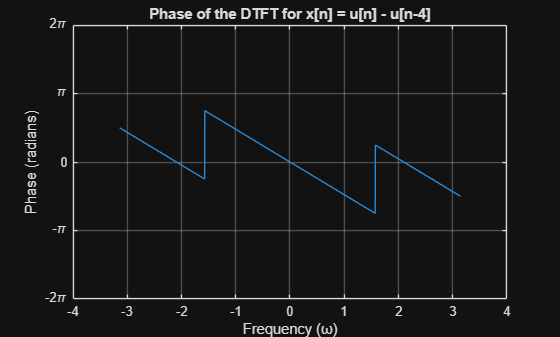

% Queswtion 2.4B]

% Define the frequency vector from -pi to pi
w = -pi:pi/1000:pi;

% 1. Calculate the DTFT X(e^jw) for the pulse x[n] = u[n] - u[n-4]
% Length L=4, centered at n=1.5
numerator = (1 - exp(-1j * 4 * w));
denominator = (1 - exp(-1j * w));
X_ejw = numerator ./ (denominator + eps); % Add epsilon to avoid division by zero at w=0

% 2. Calculate the Phase
phase_X = angle(X_ejw);

% 3. Plot the Phase
figure;
plot(w, phase_X);
title('Phase of the DTFT for x[n] = u[n] - u[n-4]');
xlabel('Frequency (ω)');
ylabel('Phase (radians)');
yticks([-3*pi -2*pi -pi 0 pi 2*pi 3*pi]); % Label y-axis ticks with multiples of pi
yticklabels({'-3\pi', '-2\pi', '-\pi', '0', '\pi', '2\pi', '3\pi'});
ylim([-2*pi 2*pi]);
grid on;